# Growth Kinetics Analaysis

clear;
clc;

## Wild Type - Reference Population

### n=1

RP_WT_1 = "/Users/Priya/testoutput/TestMammaryMonolayer/2CellType/Control/n=1/results_from_time_0/location.dat";
[RP_WT_1_numberofcells, x, RP_WT_1_yLE, RP_WT_1_yME, RP_WT_1_yTotal, RP_WT_1_ME, RP_WT_1_LE] = TimeVsNoCells(RP_WT_1);

### n=2

RP_WT_2 = "/Users/Priya/testoutput/TestMammaryMonolayer/2CellType/Control/n=2/results_from_time_0/location.dat";
[RP_WT_2_numberofcells, x, RP_WT_2_yLE, RP_WT_2_yME, RP_WT_2_yTotal, RP_WT_2_ME, RP_WT_2_LE] = TimeVsNoCells(RP_WT_2);

### n=3

RP_WT_3 = "/Users/Priya/testoutput/TestMammaryMonolayer/2CellType/Control/n=3/results_from_time_0/location.dat";
[RP_WT_3_numberofcells, x, RP_WT_3_yLE, RP_WT_3_yME, RP_WT_3_yTotal, RP_WT_3_ME, RP_WT_3_LE] = TimeVsNoCells(RP_WT_3);

### n=4

RP_WT_4 = "/Users/Priya/testoutput/TestMammaryMonolayer/2CellType/Control/n=4/results_from_time_0/location.dat";
[RP_WT_4_numberofcells, x, RP_WT_4_yLE, RP_WT_4_yME, RP_WT_4_yTotal, RP_WT_4_ME, RP_WT_4_LE] = TimeVsNoCells(RP_WT_4);

### n=5

RP_WT_5 = "/Users/Priya/testoutput/TestMammaryMonolayer/2CellType/Control/n=5/results_from_time_0/location.dat";
[RP_WT_5_numberofcells, x, RP_WT_5_yLE, RP_WT_5_yME, RP_WT_5_yTotal, RP_WT_5_ME, RP_WT_5_LE] = TimeVsNoCells(RP_WT_5);

% combine data tables from all experiments into one table

yTotal_RP_WT = cat(2,RP_WT_1_yTotal,RP_WT_2_yTotal,RP_WT_3_yTotal,RP_WT_4_yTotal,RP_WT_5_yTotal);
yLE_RP_WT = cat(2,RP_WT_1_yLE,RP_WT_2_yLE,RP_WT_3_yLE,RP_WT_4_yLE,RP_WT_5_yLE);
yME_RP_WT = cat(2,RP_WT_1_yME,RP_WT_2_yME,RP_WT_3_yME,RP_WT_4_yME,RP_WT_5_yME);

% transpose data table
time = x.';
yTotal_RP_WT_ = yTotal_RP_WT.';
yLE_RP_WT_ = yLE_RP_WT.';
yME_RP_WT_ = yME_RP_WT.';

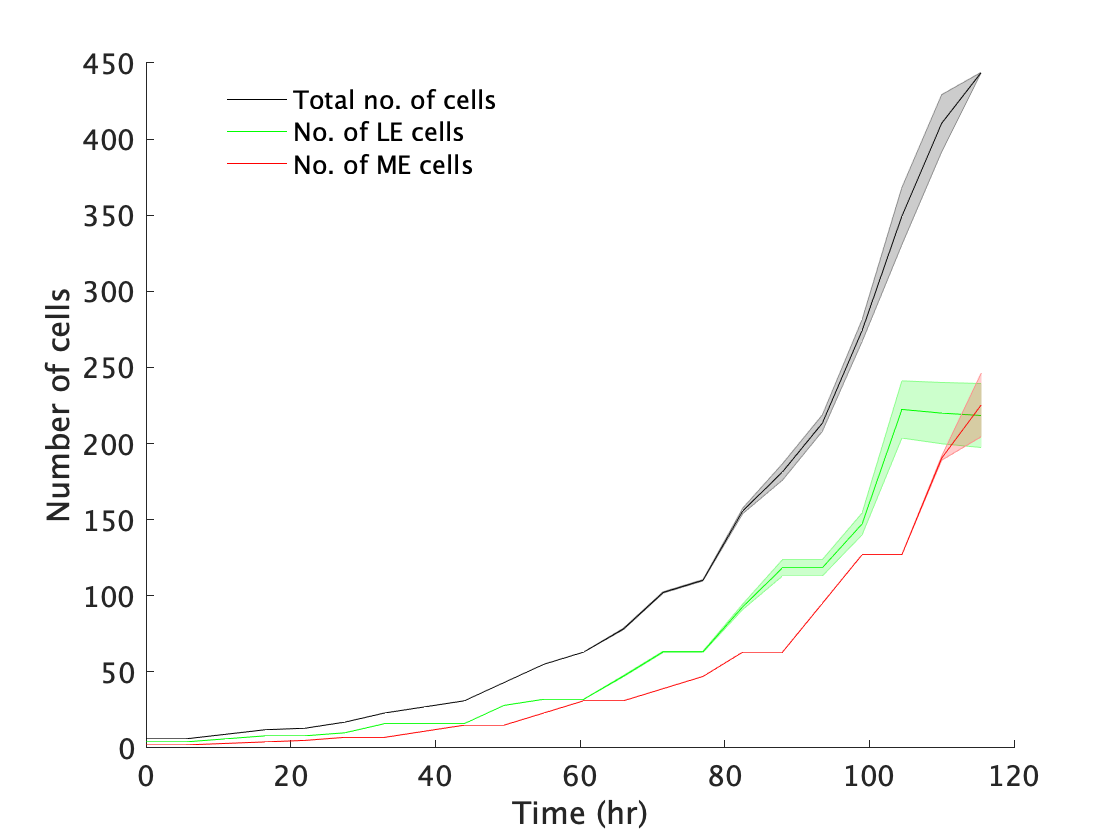

% plot data with error bars
clf

hold on; 

RP_WTtotal = shadedErrorBar(time(:,1:55:end),yTotal_RP_WT_(:,1:55:end),{@mean,@std},'lineProps','k','transparent',0);

hold off;

hold on;

RP_WTLE = shadedErrorBar(time(:,1:55:end),yLE_RP_WT_(:,1:55:end),{@mean,@std},'lineProps','-g','transparent',1);
hold off;

hold on;

RP_WTME = shadedErrorBar(time(:,1:55:end),yME_RP_WT_(:,1:55:end),{@mean,@std},'lineProps','-r','transparent',1);

hold off;

ylabel ('Number of cells')
xlabel('Time (hr)')
legend({'Total no. of cells', 'No. of LE cells', 'No. of ME cells'}, 'location', 'best')
legend('boxoff')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";

folder = '~/Desktop/';
exportgraphics(gca, 'FigureCellsvsTime_RP_WT.tiff');

movefile('FigureCellsvsTime_RP_WT.tiff', folder);

% combine data from all experiments
RP_WTnumberofcells = cat(1,RP_WT_1_numberofcells(end,:),RP_WT_2_numberofcells(end,:),RP_WT_3_numberofcells(end,:),RP_WT_4_numberofcells(end,:),RP_WT_5_numberofcells(end,:));

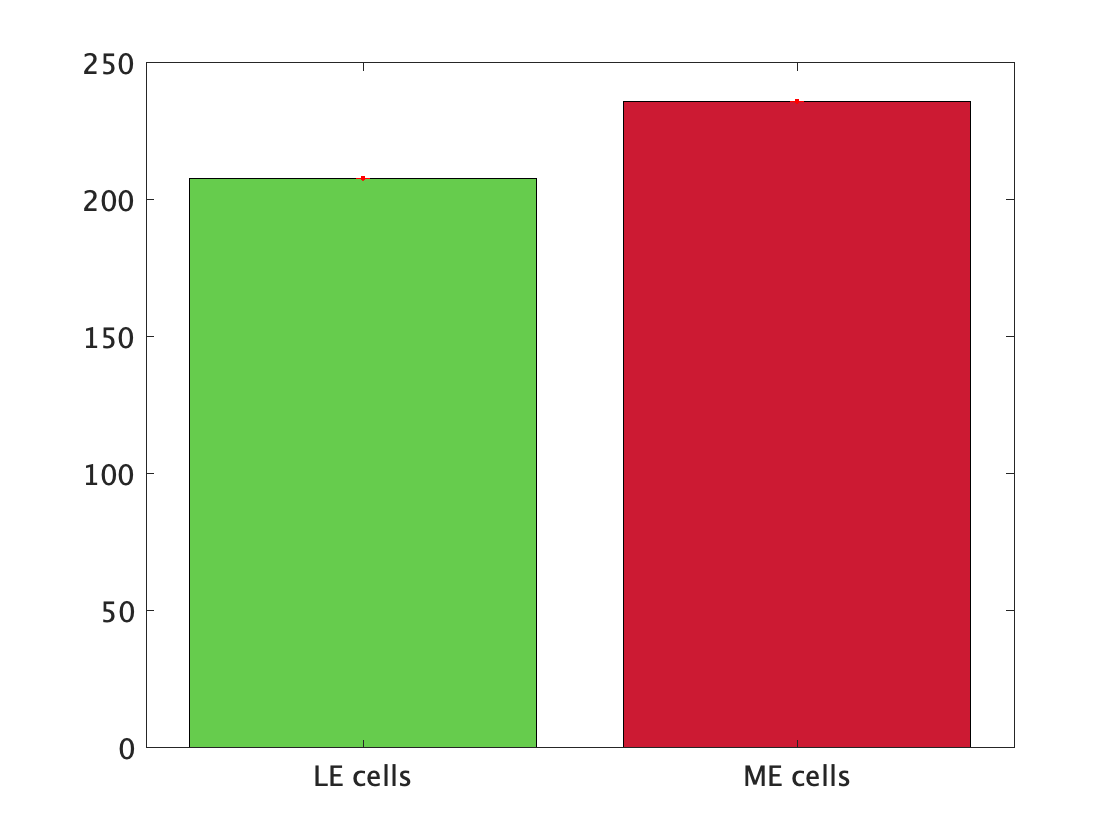

% plot data with error bars
x = [1 2];
RP_WTmeanLE = mean(RP_WTnumberofcells(:,1));
RP_WTmeanME = mean(RP_WTnumberofcells(:,2));
y = cat(2, RP_WTmeanLE,RP_WTmeanME);

WTstdLE = std(RP_WTmeanLE);
WTstdME = std(RP_WTmeanME);

error = cat(2, WTstdLE, WTstdME);

x=categorical({'LE cells', 'ME cells'});

b = bar(x,y);

%Make SD error bars 
hold on
errorbar(x,y, error, '.r')
hold off

b.FaceColor = 'flat';
b.CData(1,:) = [.4 .8 .3];
b.CData(2,:) = [.8 .1 .2];

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";

folder = '~/Desktop/';
exportgraphics(gca, 'CellCount_RP_WT.tiff');

movefile('CellCount_RP_WT.tiff', folder);

### n=1

RP_WT_1 = "/Users/Priya/testoutput/TestMammaryMonolayer/2CellType/Control/n=1/results_from_time_0/location.dat";
[x, RP_WT_1_y] = TimeVsRadius(RP_WT_1);

### n=2

RP_WT_2 = "/Users/Priya/testoutput/TestMammaryMonolayer/2CellType/Control/n=2/results_from_time_0/location.dat";
[x, RP_WT_2_y] = TimeVsRadius(RP_WT_2);

### n=3

RP_WT_3 = "/Users/Priya/testoutput/TestMammaryMonolayer/2CellType/Control/n=3/results_from_time_0/location.dat";
[x, RP_WT_3_y] = TimeVsRadius(RP_WT_3);

### n=4

RP_WT_4 = "/Users/Priya/testoutput/TestMammaryMonolayer/2CellType/Control/n=4/results_from_time_0/location.dat";
[x, RP_WT_4_y] = TimeVsRadius(RP_WT_4);

### n=5

RP_WT_5 = "/Users/Priya/testoutput/TestMammaryMonolayer/2CellType/Control/n=5/results_from_time_0/location.dat";
[x, RP_WT_5_y] = TimeVsRadius(RP_WT_5);

% combine data tables from all experiments into one table

yTotal_RP_WT = cat(2,RP_WT_1_y,RP_WT_2_y,RP_WT_3_y,RP_WT_4_y,RP_WT_5_y);

% transpose data table
time = x.';
yTotal_RP_WT_ = yTotal_RP_WT.';

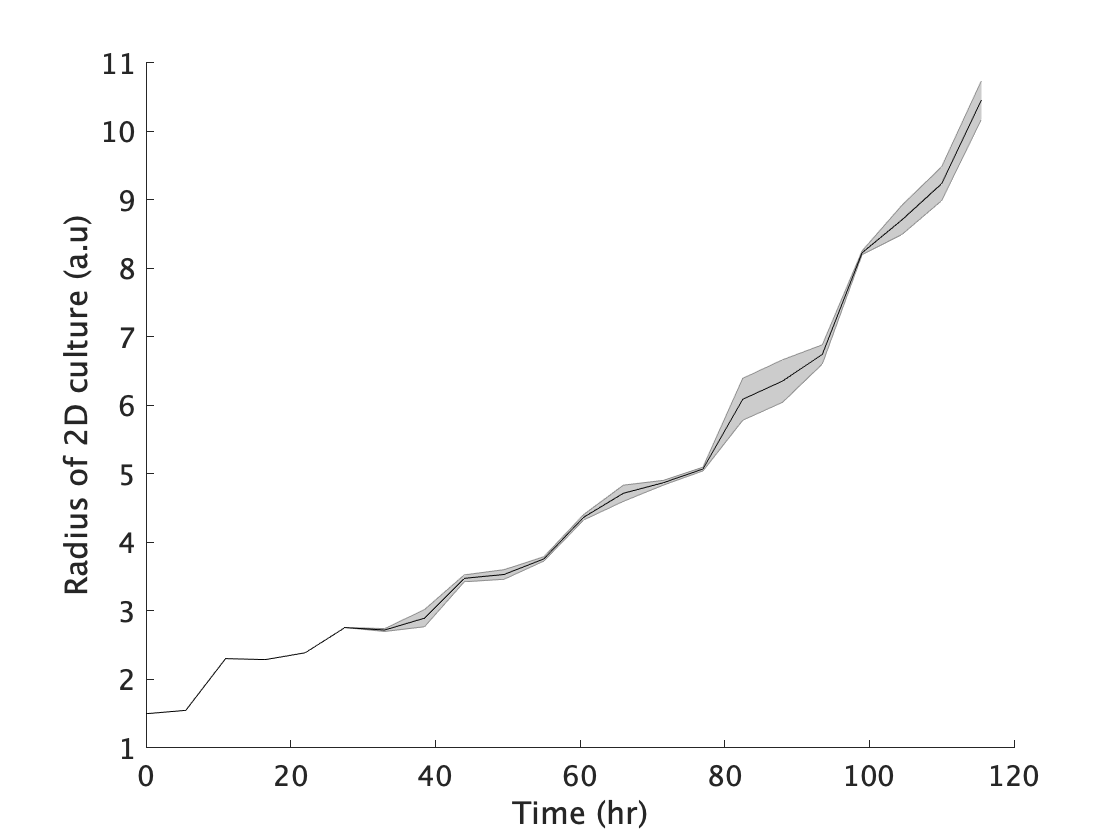

% plot data with error bars
clf

hold on; 

RP_WTtotal = shadedErrorBar(time(:,1:55:end),yTotal_RP_WT_(:,1:55:end),{@mean,@std},'lineProps','k','transparent',0);

hold off;

ylabel ("Radius of 2D culture (a.u)")
xlabel('Time (hr)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";

folder = '~/Desktop/';
exportgraphics(gca, 'FigureRadiusof2DCulture.tiff');

movefile('FigureRadiusof2DCulture.tiff', folder);